# RC Circuit Virtual Lab

In its most basic form, an RC circuit contains only a resistor and a capacitor. To charge the capacitor, a voltage source can be added. Including a switch in the circuit allows the voltage source to be turned on and off. An example of an RC circuit with a switch is shown below.

   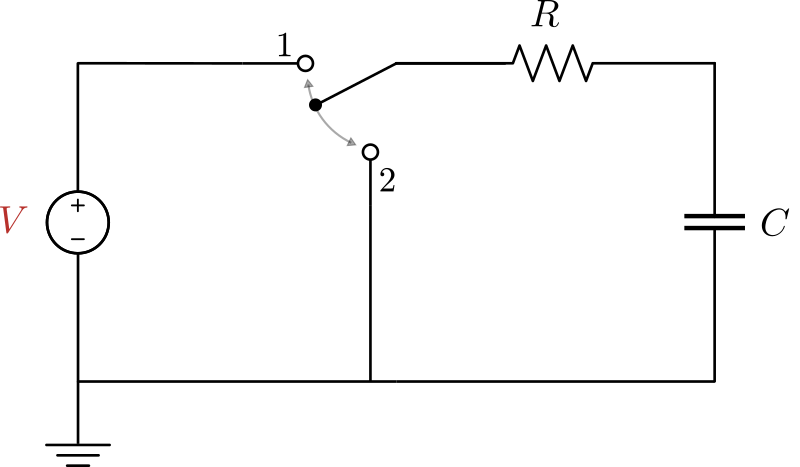

*RC circuit with a switch*

In this lab, you will analyze the RC circuit. You will start by analyzing the ODE model of the system in MATLAB and then compare your analysis to virtual measurements.

## Charging circuit

When the switch is in position 1, the voltage source is connected in series with the capacitor. As a result, the capacitor will begin charging. 

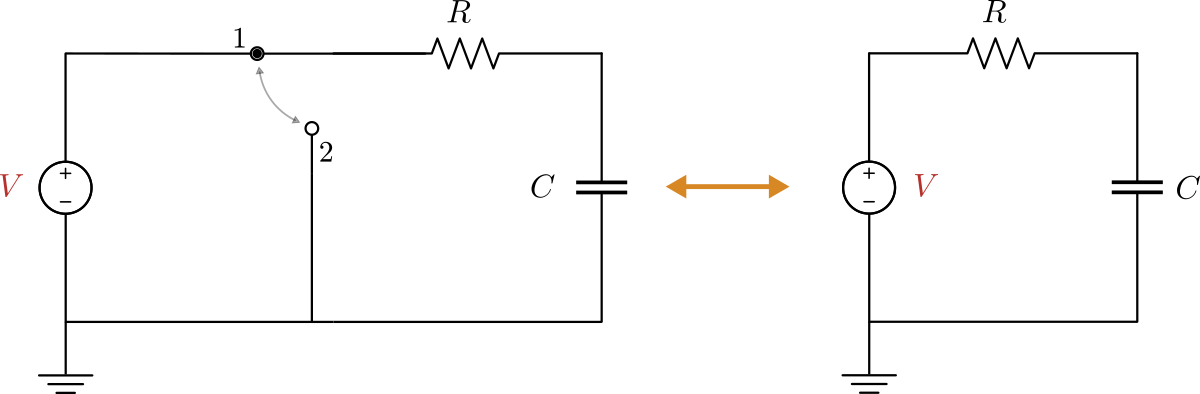

*Charging RC circuit*

The characteristics of this circuit can be modeled by applying KVL (Kirchhoff's voltage law):


$$-V + V_{R} + V_{C} = 0$$


The voltage across the capacitor in a charging circuit changes as charge builds up on the capacitor. Mathematically, this is represented by the integral of the current:


$$V_{C}(t)  = \frac{1}{C} \int_{0}^t i(\tau) d\tau + V_{C}(0)$$


The voltage drop across the capacitor is represented by Ohm's law. Therefore,


$$-V + i R + \frac{1}{C} \int_{0}^t i(\tau) d\tau + V_{C}(0) = 0$$


Taking the derivative of this equation yields the charging RC circuit ODE:

        
$$R \frac{di}{dt}  + \frac{1}{C} i= 0$$


where $R$ is the resistance, $C$ is the capacitance, and $i(t)$ is the time-dependent current.

** Task 1. **The charging circuit ODE can be solved for the current, $i(t)$. Solve for $i(t)$ and write your expression below in terms of the symbolic variables `t`, `i_0`, `R`, `C`, and store the result in `i`.

  **Pro-tip. **The notation for $e^x$ using the Symbolic Math Toolbox is

When performing multiplication of symbolic variables, use an asterisk (`*`).

syms t i_0 R C
% Replace NaN with your expression
i = i_0*exp(-t/(R*C))

$$i = i_{0}\,{\mathrm{e}}^{-\frac{t}{C\,R}}$$

** Task 2. **When the charging circuit is first connected, the capacitor is uncharged. This implies that the voltage across the capacitor is zero. Therefore, at $t = 0$,


$$-V + i(0)R = 0$$


Assume that the voltage source is $V = 12$V and the resistance is $R = 50 \Omega$. What is the initial value of the current $i(0)$ in the charging circuit? Write your answer below in .

i0 = 12/50

i0 = 0.2400

** Task 3. **Assume that $V = 12$V, $C = 1\mu\text{F}$ and $R = 50 \Omega$. Using the result of the previous two tasks, construct the function $i(t)$. Then, plot $i(t)$ from $t = 0$ to $t = 0.001$. Be sure to label the axes.

  **Pro-tip. **You can use the [`linspace`](https://www.mathworks.com/help/matlab/ref/linspace.html) function to create a time variable. For example

creates a vector `t` with 500 evenly spaced points starting at 0 and ending at 1.

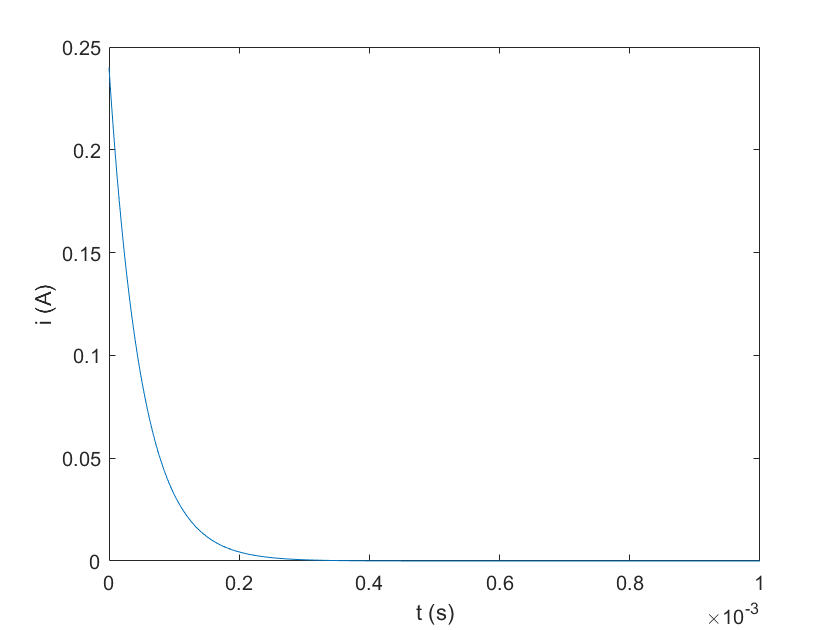

t = linspace(0,0.001,500);
V = 12;
C = 1e-6;
R = 50;
i = i0*exp(-t/(R*C));
plot(t,i)
xlabel("t (s)")
ylabel("i (A)")